# **Sistemas  de Potencia - Estudio de cortocircuito**

Un analisis de corocircuito de fallas balanceadas y desbalanceadas usando componentes simetricas permite definir criterios de diseño de los equipos para eviatr su daño y de las protecciones para seguridad de las personas y de losequipos. En el siguiente modelo de sistema de  potencia de  transmisión de 9 barras(subestaciones)  es realizado en un sistema eléctrico de potencia, mediante el procedimiento siguiente:

- Entrada de datos básicos de los generadores y ramas (líneas, transformadores).

- Formación  de la matriz de impedancia Zbus de secuencia positiva, negativa y cero.

- Cálculos de corriente de cortocicuito balanceado (trifásico) y desbalanceados.

- Valores  de tensiones  durante la falla y corrientes por llíneas durante las fallas.

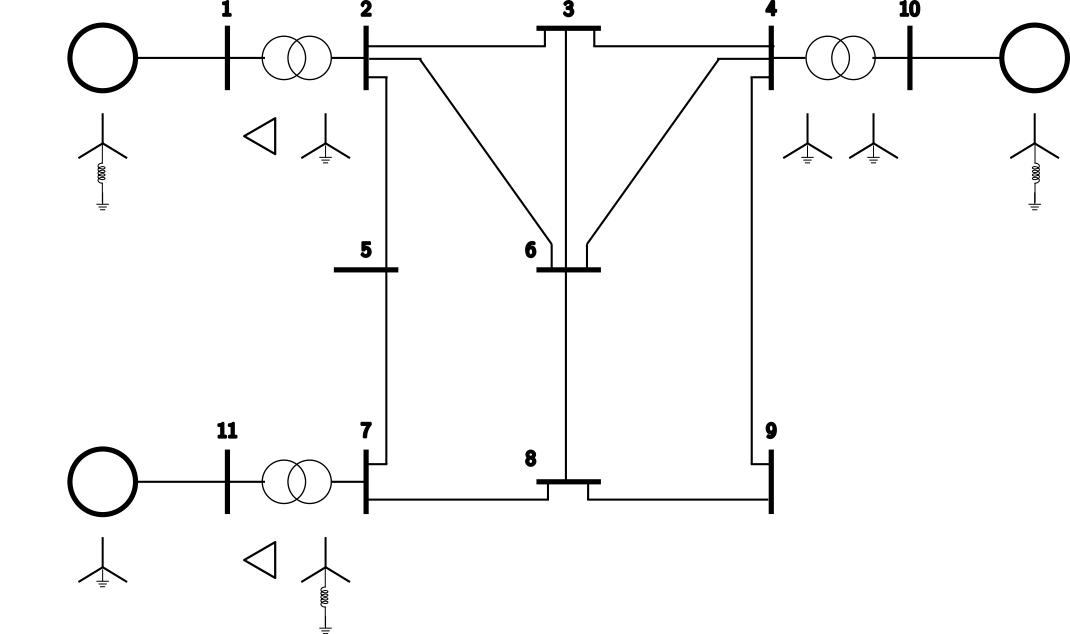

## **Entrada de datos básicos de las líneas, transformadores y generadores)**

Los datos de los generadores  estan dados en la siguiente matriz 3x4 donde cada columna representa: 1-Número de barra,  2- Reactancia subtransitoria o secuencia positiva; 3-Reactancia de secuencia cero y 4- Reactancia  de conexión del neutro.

Sbase=100;
%        11 Barras del libro de Hadi Saadat
%        Bus    Xd"     X0      Xn
%        No     pu      pu      pu       
data.gen=[1    0.20    0.06    0.05 
          10   0.15    0.04    0.05 
          11   0.25    0.08    0.00];

Los datos  de las ramas vienen dados por una matrix 14x7, donde  cada columna representa: 1- Número de barra desde, 2- Número de barra hasta, 3- Resistencia de secuencia positiva, 4- Reactancia de secuencia positiva, 5- Resistencia de secuencia cero, 4- Reactancia de secuencia cero, 5-Reactancia de neutro (trx).

%           Bus Bus   R1     X1     R0     X0    Xn    
%            nd  nh   pu     pu     pu     pu    pu
data.branch=[1   2   0.00   0.06    inf    inf   0.00 
             2   3   0.00   0.30   0.00   0.60   inf
             2   5   0.00   0.15   0.00   0.30   inf
             2   6   0.00   0.45   0.00   0.90   inf
             3   4   0.00   0.40   0.00   0.80   inf
             3   6   0.00   0.40   0.00   0.80   inf
             4   6   0.00   0.60   0.00   1.00   inf
             4   9   0.00   0.70   0.00   1.10   inf
             4  10   0.00   0.08   0.00   0.08   inf
             5   7   0.00   0.43   0.00   0.80   inf
             6   8   0.00   0.48   0.00   0.95   inf
             7   8   0.00   0.35   0.00   0.70   inf
             7  11   0.00   0.10    inf    inf   0.08
             8   9   0.00   0.48   0.00   0.90   inf];

## **Formación de la matriz de impedancias Zbus de secuencias**

La matriz de impedancia Zbus para  cada secuencia se define a partir de la inversa de la matriz de admitancia Ybus ampliada,  donde los elementos de la diagonal  esta formado por la suma de las admitancias conectadas a la barra, es decir:


$$Y_{ii}=\sum_{j=1}^{nb}y_{ij}\space j\ne  i$$


En el caso de los elementos fuera de la diagonal, viene dado por el valor negativo de las  admitancias entre barras, es decir:


$$Y_{ij}=Y_{ji}=-y_{ij}$$


data.nd=data.branch(:,1);data.nh=data.branch(:,2);data.r1=data.branch(:,3);

Unable to resolve the name 'data.branch'.

data.x1=data.branch(:,4); data.r0=data.branch(:,5);data.x0=data.branch(:,6);
data.xn=data.branch(:,7);
data.ng=data.gen(:,1);data.xg1=data.gen(:,2);data.xg0=data.gen(:,3);
data.xgn=data.gen(:,4);
data.nbus = max([data.nd' data.nh']); % número total de barras
data.nram = length(data.nd); % número total de  ramas
data.ngen = length(data.ng); % número total de  generadores
data.y1 = 1./(data.r1 + 1i*data.x1);% admitancia de sec positiva rama
data.y0 = 1./(data.r0 + 1i*data.x0);% admitancia de sec cero rama
data.yn = 1./(data.r1+1i*(data.x1+3*data.xn));% admitancia de neutro trx
data.yg1 = 1./(1i*data.xg1);% admitancia de sec positiva generador
data.yg0 = 1./(1i*(data.xg0+3*data.xgn));% admitancia de sec cero generador

% Elementos de la Ybus fuera de la diagonal
Ybus1=zeros(data.nbus,data.nbus); 
Ybus0=zeros(data.nbus,data.nbus); 
for k=1:data.nram
   Ybus1(data.nd(k),data.nh(k))=Ybus1(data.nd(k),data.nh(k))-data.y1(k);
   Ybus1(data.nh(k),data.nd(k))=Ybus1(data.nd(k),data.nh(k));
   Ybus0(data.nd(k),data.nh(k))=Ybus0(data.nd(k),data.nh(k))-data.y0(k);
   Ybus0(data.nh(k),data.nd(k))=Ybus0(data.nd(k),data.nh(k));
end
% Elementos de la Ybus en la diagonal          
for  n=1:data.nbus
     for k=1:data.nram
         if data.nd(k)==n
            Ybus1(n,n) = Ybus1(n,n) + data.y1(k);
            Ybus0(n,n) = Ybus0(n,n) + data.y0(k) + data.yn(k);
         elseif data.nh(k)==n
            Ybus1(n,n) = Ybus1(n,n) + data.y1(k);
            Ybus0(n,n) = Ybus0(n,n) + data.y0(k) + data.yn(k);
         else
         end
     end
end
% Incorporacion elementos de generador
for  n=1:data.ngen
      Ybus1(data.ng(n),data.ng(n)) = Ybus1(data.ng(n),data.ng(n)) + data.yg1(n);
      Ybus0(data.ng(n),data.ng(n)) = Ybus0(data.ng(n),data.ng(n)) + data.yg0(n);
end
% Calculo de Zbus
Zbus1=eye(data.nbus)/Ybus1;Zbus0=eye(data.nbus)/Ybus0;
clear n k


## Cálculos de cortocircuito balanceado (trifásico) y desbalanceado

En el caso de cortocircuito trifásico balanceado en una barrra i, el valor de la corriente de falla viene dada por:


$$I_{i}^{a}=\frac{V_{i (0)}^{a}}{Z_{ii}^{1}+Z_{f}}$$


En el caso de cortocircuito monofásico a tierra, el valor de la corriente de falla viene dada por:


$$I_{i}^{0}=I_{i}^{1}=I_{i}^{2}=\frac{V_{i (0)}^{a}}{Z_{ii}^{1}+Z_{ii}^{2}+Z_{ii}^{0}+3Z_{f}}$$


Donde a = 1$\angle$120º,las corrientes de fase son obtenidas mdiiante


$$\pmatrix{I_{i}^{a}\cr
I_{i}^{b}\cr
I_{i}^{c}}=\pmatrix{1&1 &1\cr
1&a^{2}&a\cr
1&a &a^{2}}\pmatrix{I_{i}^{0}\cr
I_{i}^{0}\cr
I_{i}^{0}}=\pmatrix{3I_{i}^{0}\cr
0\cr
0}$$


El cortocircuito bifásco entre fases, los valores de la corriente de falla de secuencia son los siguientes:


$$\matrix{I_{i}^{0}=0\cr
I_{i}^{1}=-I_{i}^{2}=\frac{V_{i (0)}^{a}}{Z_{ii}^{1}+Z_{ii}^{2}+Z_{f}}}$$


El cortocircuito bifásico  a tierra, las corrientes de falla de secuencia son:


$$\matrix{ I_{i}^{0}=-\frac{V_{i(0)}-Z_{ii}^{1}I_{i}^{1}}{Z_{ii}^{0}+3Z_{f}}\cr
I_{i}^{2}=-\frac{V_{i(0)}-Z_{ii}^{1}I_{i}^{1}}{Z_{ii}^{2}}\cr
I_{i}^{1}=\frac{V_{i(0)}}{Z_{ii}^{1} + \frac{Z_{ii}^{2}(Z_{ii}^{0}+3Z_{f})}{Z_{ii}^{2}+Z_{ii}^{0}+3Z_{f}}}}$$


% Entrada de la barra fallada
bmax=data.nbus;
nbf=  8;
% Resistencia de falla en pu
Rf =  0;
% Reactancia de  falla en pu
Xf =  0;
% Tipo de falla
Falla = 3;

a = cos(2*pi/3) + 1i*sin(2*pi/3);
A=[1 1 1;1 a^2 a; 1 a a^2];
switch Falla
    % Valores de Icc 3f
    case 1
        cc.I3fa= 1/(Zbus1(nbf,nbf)+(Rf+1i*Xf));
        cc.I3fb= cc.I3fa*a;cc.I3fc= cc.I3fa*a^2;
        cc.I3f=[cc.I3fa;cc.I3fb;cc.I3fc];
        u=real(cc.I3f);
        v=imag(cc.I3f);
        
        c=compass(u,v);
        title('I_{cc}^{3f}= ',num2str(abs(cc.I3fa)))
        c1 = c(1);
        c1.LineWidth = 1;
        c1.Color = 'r';
        c2 = c(2);
        c2.LineWidth = 1;
        c2.Color = 'g';
    case 2
    % Valores de Icc 1f
        cc.I1f0= 1/(2*Zbus1(nbf,nbf)+Zbus0(nbf,nbf)+3*(Rf+1i*Xf));
        cc.I1f=A*[cc.I1f0;cc.I1f0;cc.I1f0];
        u=real(cc.I1f);
        v=imag(cc.I1f);
        
        c=compass(u,v);
        title('I_{cc}^{1f}= ',num2str(abs(cc.I1f(1))))
        c1 = c(1);
        c1.LineWidth = 1;
        c1.Color = 'r';
        c2 = c(2);
        c2.LineWidth = 1;
        c2.Color = 'g';
    case  3
        % Valores de Icc 2f
        cc.I2f1= 1/(2*Zbus1(nbf,nbf)+(Rf+1i*Xf));
        cc.I2f=A*[0;cc.I2f1;-cc.I2f1];

        u=real(cc.I2f);
        v=imag(cc.I2f);
        c=compass(u,v);
        title('I_{cc}^{2f}= ',num2str(abs(cc.I2f(2))))
        c1 = c(1);
        c1.LineWidth = 1;
        c1.Color = 'r';
        c2 = c(2);
        c2.LineWidth = 1;
        c2.Color = 'g';
    case 4
        % Valores de Icc 2f-g
        cc.I2gf1= 1/(Zbus1(nbf,nbf)+(Zbus1(nbf,nbf)*(Zbus0(nbf,nbf)+3*(Rf+1i*Xf))/...
            (Zbus1(nbf,nbf)+Zbus0(nbf,nbf)+3*(Rf+1i*Xf))));
        cc.I2gf2= -(1-Zbus1(nbf,nbf)*cc.I2gf1)/Zbus1(nbf,nbf);
        cc.I2gf0= -(1-Zbus1(nbf,nbf)*cc.I2gf1)/(Zbus0(nbf,nbf)+3*(Rf+1i*Xf));
        cc.I2gf=A*[cc.I2gf0;cc.I2gf1;cc.I2gf2];

        u=real(cc.I2gf);
        v=imag(cc.I2gf);
        c=compass(u,v);
        title('I_{cc}^{2f-g}= ',num2str(abs(cc.I2gf(2))))
        c1 = c(1);
        c1.LineWidth = 1;
        c1.Color = 'r';
        c2 = c(2);
        c2.LineWidth = 1;
        c2.Color = 'g';
end

## Valores  de tensiones  durante la falla y corrientes por líneas durante las fallas

Los valores de las tensiones en las barras durante la  falla y las corrientes por las líneas,viene dado por:


$$\matrix{ V_{i}^{0}(F)=0-Z_{ik}^{0}I_{i}^{0}\cr
V_{i}^{1}(F)=V_{i}^{1}(0)-Z_{ik}^{1}I_{i}^{1}\cr
V_{i}^{2}(F)=0-Z_{ik}^{2}I_{i}^{2}}$$


las corrientes por las líneas


$$\matrix{ I_{ij}^{0}=\frac{V_{i}^{0}(F)-V_{j}^{0}(F)}{z_{ij}^{0}}\cr
 I_{ij}^{1}=\frac{V_{i}^{1}(F)-V_{j}^{1}(F)}{z_{ij}^{1}}\cr
 I_{ij}^{2}=\frac{V_{i}^{2}(F)-V_{j}^{2}(F)}{z_{ij}^{2}}}}$$


% Tensiones en las barras
% for n=1:data.nbus
%     cc.vf0(n)=-Zbus0(n,nbf)*
% end
switch Falla
    case 1
    for n=1:data.nbus
        cc.vf0(n)=-Zbus0(n,nbf)*0;
        cc.vf1(n)=1-Zbus1(n,nbf)*cc.I3fa;
        cc.vf2(n)=-Zbus1(n,nbf)*0;
        cc.vf(:,n)=A*[cc.vf0(n);cc.vf1(n);cc.vf2(n)];
    end
    case 2
    for n=1:data.nbus
        cc.vf0(n)=-Zbus0(n,nbf)*cc.I1f0;
        cc.vf1(n)=1-Zbus1(n,nbf)*cc.I1f0;
        cc.vf2(n)=-Zbus1(n,nbf)*cc.I1f0;
        cc.vf(:,n)=A*[cc.vf0(n);cc.vf1(n);cc.vf2(n)];
    end
    case 3
    for n=1:data.nbus
        cc.vf0(n)=-Zbus0(n,nbf)*0;
        cc.vf1(n)=1-Zbus1(n,nbf)*cc.I2f1;
        cc.vf2(n)=-Zbus1(n,nbf)*(-cc.I2f1);
        cc.vf(:,n)=A*[cc.vf0(n);cc.vf1(n);cc.vf2(n)];
    end
    case 4
    for n=1:data.nbus
        cc.vf0(n)=-Zbus0(n,nbf)*cc.I2gf0;
        cc.vf1(n)=1-Zbus1(n,nbf)*cc.I2gf1;
        cc.vf2(n)=-Zbus1(n,nbf)*cc.I2gf2;
        cc.vf(:,n)=A*[cc.vf0(n);cc.vf1(n);cc.vf2(n)];
    end
end
% Voltaje en barra despues de la falla
nb=1;
u=real(cc.vf(:,nb));
v=imag(cc.vf(:,nb));
c=compass(u,v);
title('V_{f}')
c1 = c(1);
c1.LineWidth = 1;
c1.Color = 'r';
c2 = c(2);
c2.LineWidth = 1;
c2.Color = 'g';

ram=data.nram;
rams = 8;
for n=1:data.nram
    cc.Iram0(n)=(cc.vf0(data.nd(n))-cc.vf0(data.nh(n)))/(data.r0(n) + 1i*data.x0(n));
    cc.Iram1(n)=(cc.vf1(data.nd(n))-cc.vf1(data.nh(n)))/(data.r1(n) + 1i*data.x1(n));
    cc.Iram2(n)=(cc.vf2(data.nd(n))-cc.vf2(data.nh(n)))/(data.r1(n) + 1i*data.x1(n));
    cc.Iram(:,n)=A*[cc.Iram0(n);cc.Iram1(n);cc.Iram2(n)];
end
x=1:data.nram;
%bar(x',[abs(cc.Iram(1,:))]',x',[abs(cc.Iram(2,:))]',x',[abs(cc.Iram(3,:))]')
bar(abs(cc.Iram)')
u=real(cc.Iram(:,rams));
v=imag(cc.Iram(:,rams));
c=compass(u,v);
title('I_{rama} ',num2str(rams))
c1 = c(1);
c1.LineWidth = 1;
c1.Color = 'r';
c2 = c(2);
c2.LineWidth = 1;
c2.Color = 'g';